Import the filtered data set

clc;clear;
load("mfcc_mel.mat")

Import filtered data to extract features and labels

AllFeature=MFCCs(:,1)

AllFeature = 920×1 cell 数组
    {26×244 double}
    {26×341 double}
    {26×328 double}
    {26×663 double}
    {26×374 double}
    {26×295 double}
    {26×468 double}
    {26×421 double}
    {26×252 double}
    {26×783 double}
    {26×487 double}
    {26×461 double}
    {26×457 double}
    {26×532 double}
    {26×532 double}
    {26×532 double}


AllLabel=MFCCs(:,2)

AllLabel = 920×1 cell 数组
    {[1]}
    {[1]}
    {[3]}
    {[4]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}
    {[1]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}


AllLabel=cell2mat(AllLabel)

AllLabel = 920×1 int32 列向量
   1
   1
   3
   4
   2
   2
   2
   2
   2
   2


AllLabel=categorical(AllLabel)

AllLabel = 920×1 categorical 数组
     1 
     1 
     3 
     4 
     2 
     2 
     2 
     2 
     2 
     2 
     1 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 


Separate training set and test set

n=randperm(size(AllLabel,1));
TrainFeature=AllFeature(n(1:736))

TrainFeature = 736×1 cell 数组
    {26×1016 double}
    {26×1077 double}
    {26×825  double}
    {26×1010 double}
    {26×648  double}
    {26×407  double}
    {26×794  double}
    {26×1387 double}
    {26×546  double}
    {26×748  double}
    {26×454  double}
    {26×1028 double}
    {26×504  double}
    {26×289  double}
    {26×874  double}
    {26×602  double}


TrainLabel=AllLabel(n(1:736))

TrainLabel = 736×1 categorical 数组
     2 
     2 
     2 
     2 
     2 
     2 
     4 
     2 
     2 
     2 
     3 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 


TestFeature=AllFeature(n(737:end))

TestFeature = 184×1 cell 数组
    {26×1063 double}
    {26×825  double}
    {26×591  double}
    {26×450  double}
    {26×971  double}
    {26×681  double}
    {26×435  double}
    {26×626  double}
    {26×490  double}
    {26×995  double}
    {26×1010 double}
    {26×457  double}
    {26×855  double}
    {26×185  double}
    {26×1192 double}
    {26×528  double}


TestLabel=AllLabel(n(737:end))

TestLabel = 184×1 categorical 数组
     2 
     2 
     2 
     4 
     2 
     2 
     4 
     2 
     2 
     2 
     2 
     2 
     2 
     1 
     2 
     4 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 


Build a deep learning network

**Use the bidirectional LSTM layer bilstmLayer to analyze the sequence forward and backward**

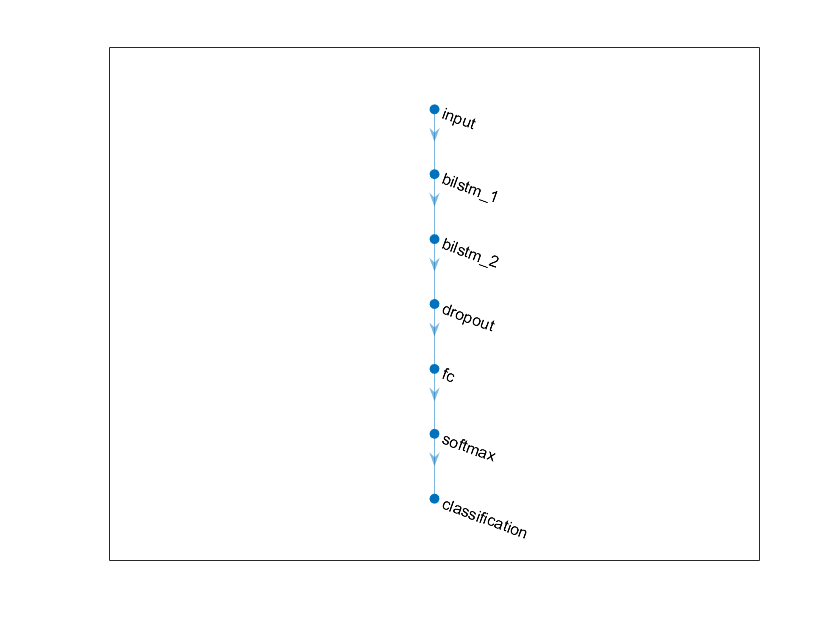

layers = [
    sequenceInputLayer(26,"Name","input")
    bilstmLayer(125,"Name","bilstm_1")
    bilstmLayer(100,"Name","bilstm_2","OutputMode","last")
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(4,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];
plot(layerGraph(layers));

Train

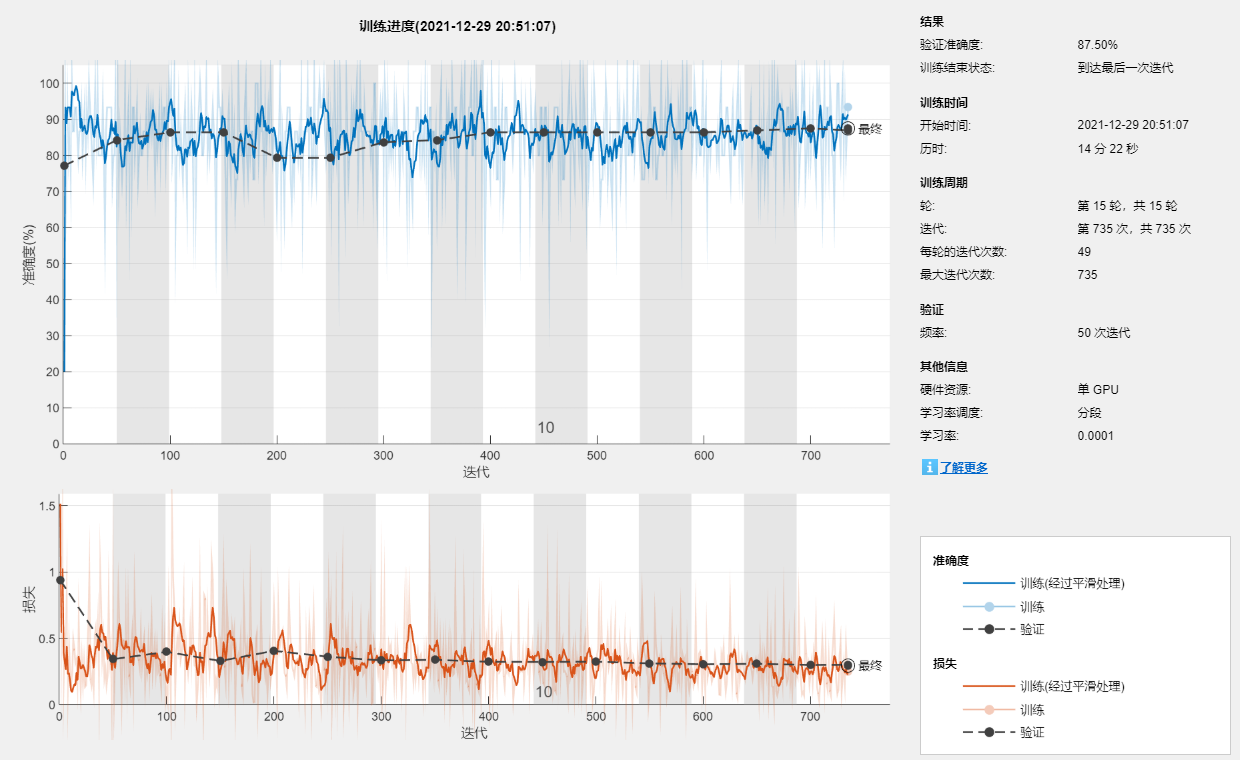

miniBatchSize = 15;
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.0100,...
    'LearnRateSchedule','piecewise', ...
    "LearnRateDropFactor",0.1, ...
    "LearnRateDropPeriod",5, ...
    'ExecutionEnvironment','auto', ...
    'MaxEpochs',15, ...
    'MiniBatchSize',miniBatchSize, ...
    'ValidationData',{TestFeature,TestLabel}, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(TrainFeature,TrainLabel,layers,options);

Calculation accuracy

YValPred = classify(net,TestFeature);
valAccuracy = mean(TestLabel==YValPred)*100;
print('Accuracy = %0.1f',valAccuracy)

错误使用 DAGNetwork/classify (第 175 行)
Out of memory on device. To view more detail about available memory on the GPU, use 'gpuDevice()'. If the problem persists, reset the GPU by calling 'gpuDevice(1)'.

出错 SeriesNetwork/classify (第 528 行)
            [labels, scores] = this.UnderlyingDAGNetwork.classify(X, varargin{:});